# Compare Gasoline Cost

Compares the cost of gasoline in Australia with other countries. 

The true cost (in terms of hours of labor) of a liter of gasoline is calculated from raw price data and average hourly wages. The cost in Australia is compared to Canada, Germany, and Mexico. Statistics are calculated for the difference bewteen Australia and Canada.

## Load gas price data from file

Replace the missing Australian price in 1990 with the price in 1991.

load gCosts
Australia(1) = Australia(2);

## Plot the gas prices for all four countries.

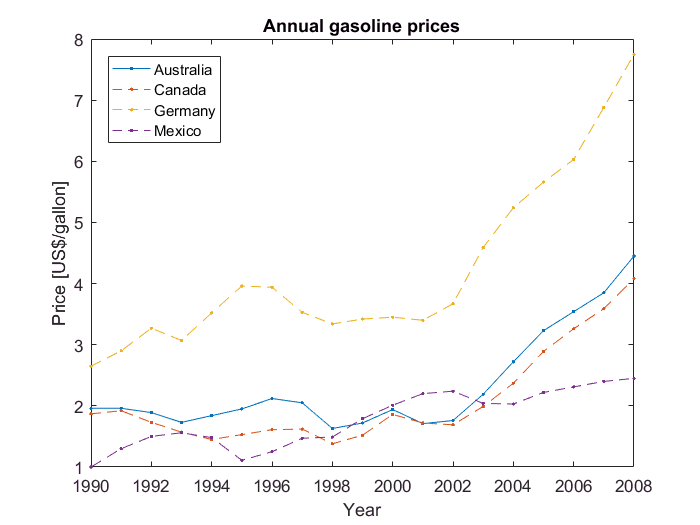

plot(Year,Australia,'.-')
hold on
plot(Year,Canada,'.--')
plot(Year,Germany,'.--')
plot(Year,Mexico,'.--')
hold off
% Add annotations
legend(country,'Location','northwest')
title('Annual gasoline prices')
xlabel('Year')
ylabel('Price [US$/gallon]')

## Convert the prices to costs.

The units for cost are work hours (based on average income) per liter.


$$\frac{hour}{L} = \frac{gal}{L}\times \frac{USD}{gal} \div \frac{USD}{hr}$$


gal2lit = 0.2642;
Australia = gal2lit*Australia/hourlyAus;
Canada = gal2lit*Canada/hourlyCan;
Germany = gal2lit*Germany/hourlyGer;
Mexico = gal2lit*Mexico/hourlyMex;

Plot the costs.

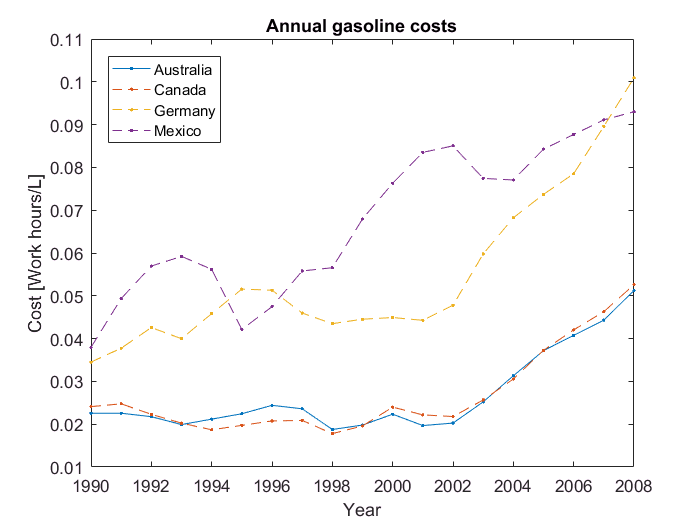

plot(Year,Australia,'.-')
hold on
plot(Year,Canada,'.--')
plot(Year,Germany,'.--')
plot(Year,Mexico,'.--')
hold off
% Add annotations
title('Annual gasoline costs')
legend(country,'Location','NorthWest')
xlabel('Year')
ylabel('Cost [Work hours/L]')

## Calculate the difference between Australian and Canadian cost.

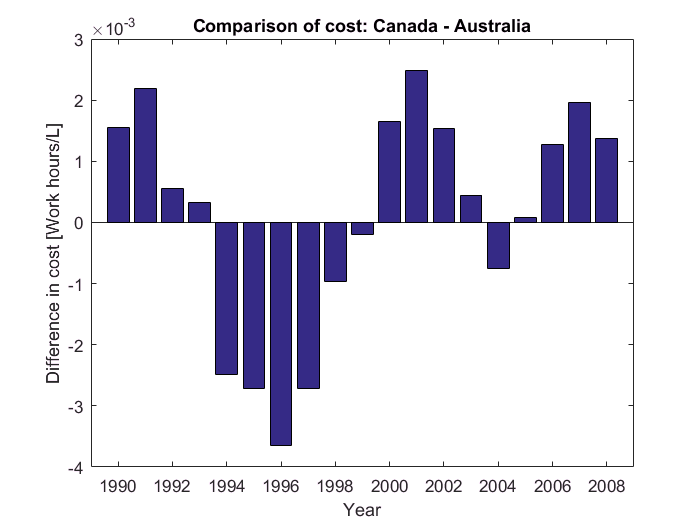

AuCaDiff = Canada - Australia;

% Plot the result
bar(Year,AuCaDiff)
xlabel('Year')
ylabel('Difference in cost [Work hours/L]')
title('Comparison of cost: Canada - Australia')
xlim([1989 2009])

## Calculate statistics on the difference.

What was the average difference in cost between Australia and Canada?

avgDiff = mean(AuCaDiff)

avgDiff = 1.0320e-04

Find the absolute value of the difference. When did the greatest cost difference occur?

absDiff = abs(AuCaDiff);
[biggestDiff,idx] = max(absDiff);
Year(idx)

ans = 1996

## Plot the Australian and Canadian costs against each other.

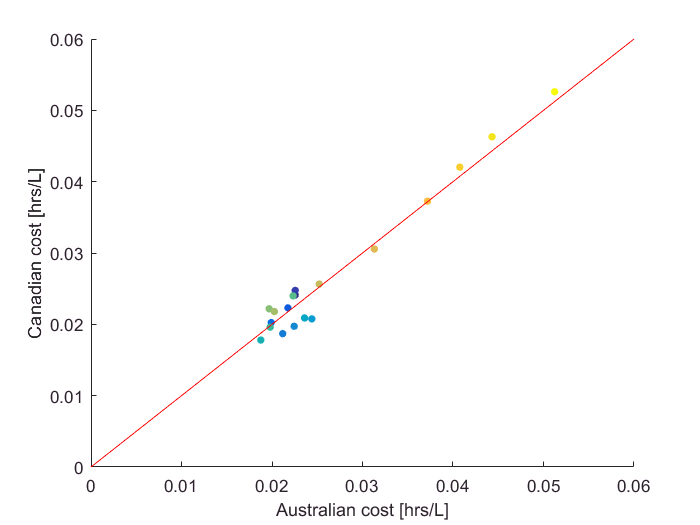

scatter(Australia,Canada,20,Year,'Filled')
xlim([0 0.06])
% Add 45 degree line.
AuLimits = xlim;
hold on
plot(AuLimits,AuLimits,'r')
hold off
% Add annotations.
xlabel('Australian cost [hrs/L]')
ylabel('Canadian cost [hrs/L]')